# Simulation-based investigation of evolutionary stability of extortionate zero-determinant strategies

## Abstract

## Introduction

Press and Dyson (2012) introduced a new class of strategies for the iterated prisoner's dilemma (IPD) as well as for other types of similar two-player games. In their seminal article the authors make at least three discoveries about the IPD:

- There exists a class of (zero-determinant, ZD) strategies which allow any player to unilaterally enforce a linear relationship between the two player's payoffs in the stationary state. This allows i.a. for one player to demand an extortionate share of payoffs in the game.

- For any two strategies with different memory size, there exists an equivalent simpler version of the longer-memory strategy with the same memory size as the shorter memory strategy.

- The nature of the IPD game changes fundamentally as soon as at least one player has knowledge of ZD strategies. In the case where e.g. one player has knowledge about ZD strategies and demands and extortionate share, and the other player has at least a Theory of Mind of its opponent, the IPD is reduced to an ultimatum game.

While the article by Press and Dyson (2012) only deals with the case of one-round memory strategy, (2) implies that their findings indeed hold for IPD games in general. The groundbreaking nature of their contribution comes from the fact that 

Regarding the major contribution (1), Press and Dyson (2012) show that it is possible for one player to unilaterally enforce a linear relation between their two respective payoffs $s_x ,s_y$ in the stationary stationary only by setting his own strategy vector $p$ independent of the other players strategy:


$$\alpha s_x +\beta s_y +\gamma =0$$


This gives the player at least two possibilities: he can set his opponent's score to a fixed value, or he can set his own score to be factor of his opponent's score (setting his own score is not possible, as shown by Press and Dyson (2012)). The latter strategy is particularly interesting, as it is possible to set this factor to a value $>1$ and thus demand and extortionate share. This is achieved by solving the following system of equations:


$$p'=\Phi \left(S_x −P−\chi \left(S_y −P\right)\right)$$


Where $p'=\left(p_1 −1,p_{2\text{ }} −2,p_3 ,p_4 \right)$ contains the probabilities constituting player X's strategy, $S_x =\left(R,S,T,P\right)$ and $S_y =\left(R,T,S,P\right)$ are the payoff vectors for the two players and $\chi \text{ }$ governs the extortion factor, giving formulae as a function of $\Phi \text{ }$ and $\chi \text{ }$for player X's probabilities as well as an upper bound for $\Phi \text{ }$ as a function of $\chi \text{ }$. Furthermore $\Phi >0$ and $\chi \text{ }\ge 1$. The well-known Tit-for-Tat-strategy for the IPD 

## Demonstration

Press and Dyson (2012) show that when one player plays a ZD strategy then the payoff for both players is maximized if the other player chooses to cooperate unconditionally. Using the standard IPD payoffs $\left(R,S,T,P\right)=\left(3,0,5,1\right)$ the maximum expected payoffs for the two players are:

Phi = 0.1;
chi = 2;
NRounds = 20000;
PDGame = Game([3 0;5 1]);
ExtPlayer = PlayerExtortionate(Phi,chi);
AllCPlayer = PlayerAllC;
[ExtPlayer,AllCPlayer] = PDGame.playNRounds(NRounds,ExtPlayer,AllCPlayer);
plot([ExtPlayer.AveragePayoffHistory AllCPlayer.AveragePayoffHistory])
hold on
plot([0 NRounds],[(2+chi*13)/(2+chi*3) (2+chi*13)/(2+chi*3)])
plot([0 NRounds],[(12+3*chi)/(2+3*chi) (12+3*chi)/(2+3*chi)])
ylim([0 5])

The average payoff by the extortionate and the cooperative player as well as their ratio are given by:

[ExtPlayer.AveragePayoffHistory(end) ...
    AllCPlayer.AveragePayoffHistory(end) ...
    ExtPlayer.AveragePayoffHistory(end)/AllCPlayer.AveragePayoffHistory(end)]

This compares well to the predicted values, showing that asymptotic convergence can be achieved after 20000 plays.

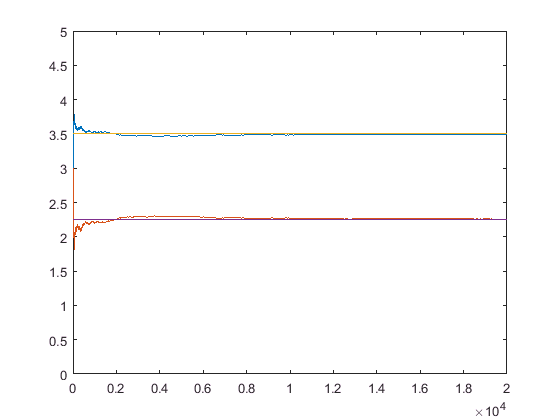

[(2+chi*13)/(2+chi*3) (12+3*chi)/(2+3*chi) ...
    ((2+chi*13)/(2+chi*3))/((12+3*chi)/(2+3*chi))]

## Sensitivity analysis

vecPhi = [0.1 0.05 0.025];
vecChi = [2 3 5];


ans =     3.4953    2.2571    1.5486


figure 
for i = 1:9
    try

ans =     3.5000    2.2500    1.5556


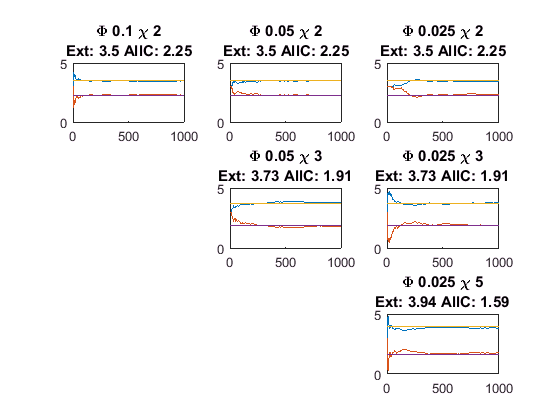

        Phi = vecPhi(mod(i-1,3)+1);
        chi = vecChi(ceil(i/3));
        
        ExtPlayer = PlayerExtortionate(Phi,chi);
        AllCPlayer = AllCPlayer.resetHistory;
        [ExtPlayer,AllCPlayer] = PDGame.playNRounds(1000,ExtPlayer,AllCPlayer);
        
        subplot(3,3,i)
        plot([ExtPlayer.AveragePayoffHistory AllCPlayer.AveragePayoffHistory])
        hold on
        plot([0 1000],[(2+chi*13)/(2+chi*3) (2+chi*13)/(2+chi*3)])
        plot([0 1000],[(12+3*chi)/(2+3*chi) (12+3*chi)/(2+3*chi)])
        ylim([0 5])
        title(['\Phi ' num2str(Phi) ' \chi ' num2str(chi) newline 'Ext: ' ...
            num2str(round(((2+chi*13)/(2+chi*3))*100)/100) ' AllC: ' ...
            num2str(round(((12+3*chi)/(2+3*chi))*100)/100)])
    end
end

## Evolutionary dynamics

GameAgainstAllC = Game([3 0;5 1]);
GameAgainstAllC = GameAgainstAllC.createPopulation(500,'PlayerAllC()',0.5,...
    'PlayerExtortionate(0.1,2)',0.5);
GameAgainstAllC = GameAgainstAllC.runNGenerationTournament(1000,100);

disp('Exortationate against cooperative strategy')

Exortationate against cooperative strategy


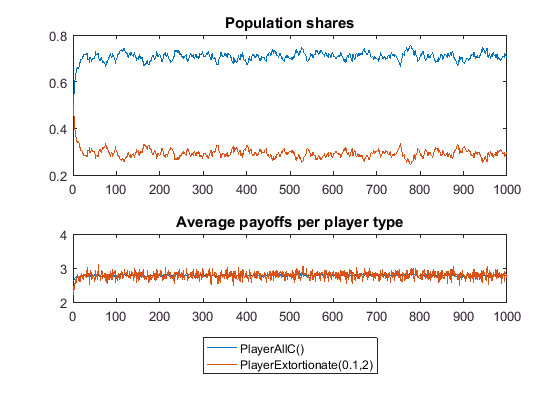

subplot(2,1,1)
plot(GameAgainstAllC.PopulationShareHistory)
title('Population shares')

subplot(2,1,2)
plot(GameAgainstAllC.PlayerTypeAvgPayoffHistory)
legend(GameAgainstAllC.PlayerTypes,'Location','southoutside')
title('Average payoffs per player type')

GameAgainstAllD = Game([3 0;5 1]);
GameAgainstAllD = GameAgainstAllD.createPopulation(500,'PlayerAllD()',0.5,...
    'PlayerExtortionate(0.1,2)',0.5);
GameAgainstAllD = GameAgainstAllD.runNGenerationTournament(1000,100);

## References

Adami, C., & Hintze,  A. (2013). Evolutionary instability of zero-determinant strategies  demonstrates that winning is not everything. *Nature communications*, *4:2193*.

Bauso, D. (2016). *Game theory with engineering applications*. Society for Industrial and Applied Mathematics.

Hilbe, C., Nowak, M. A., & Sigmund, K. (2013). Evolution of extortion in iterated prisoner’s dilemma games. *Proceedings of the National Academy of Sciences*, *110*(17), 6913-6918.

Press, W. H., &  Dyson, F. J. (2012). Iterated Prisoner’s Dilemma contains strategies  that dominate any evolutionary opponent. *Proceedings of the National Academy of Sciences*, *109*(26), 10409-10413.